# Title: ACL reconstuction and ACL repair gait analysis

# Date: 20/02/2022

# Name: Liam Brosnan

# Progress

I've found live editor mode on matlab that seems to be a better way to present my work, with the email exchange with Matt and talking with you I have been able to find which axis represents which column. From this I have plotted the x,y and z axis data for the hips knees and ankles. Using the hold function I've been able to compare the left and right side. With Matt's clarification on the first frame data, I have also added the time domain to the x-axis for each plot with the corrected adjustment. This now allows me to look at each of the gait cycles correctly.

# Future

The next steps I'll be taking, I'll be extracting each of the gait cycles from the left and right hip, knee, and ankle into a new array and then putting them into a table to see the time vs angle for each of the gait cycle. From this I'll add a new plot with each of the gait cycles plotted on top of each other along with the mean plot for the hip, knee and ankle as you suggested.

## Loading of variables

load("Gait Analysis Variables.mat");
time_domain = [1.59:0.01:4.45]'; % seconds (s)

## Data collection

acq = btkReadAcquisition('example_data_test.c3d');  % extract the acquired data
[markers, markerInfo.units] = btkGetMarkers(acq);   % extract the markers data
[angles, anglesInfo] = btkGetAngles(acq);  % collect all angles from the markers data
[events] = btkGetEvents(acq)  % extract events from the data collection

events = struct with fields:
     Left_Foot_Strike: [1.8900 3 4.1100]
       Right_Foot_Off: [2.0200 3.1200 4.2600]
    Right_Foot_Strike: [2.4500 3.5600]
        Left_Foot_Off: [2.5800 3.7100]


# Plotting X - axis angles

## Left and Right Hip Angle plot

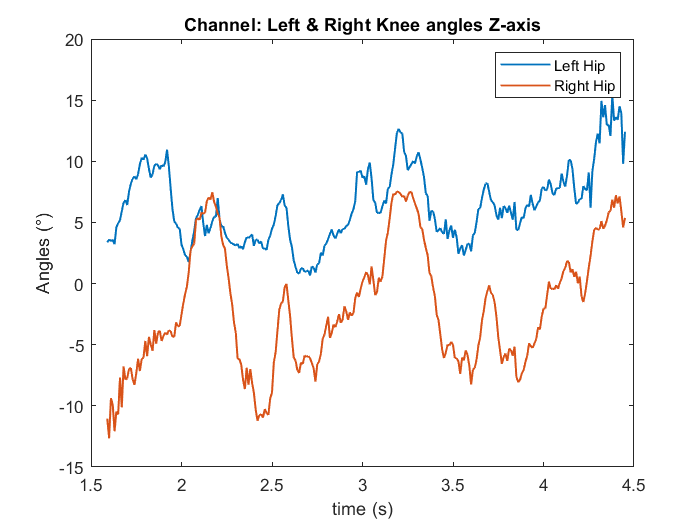

figure('Name','Channel: Left & Right Hip angles Z-axis') %create figure
plot(time_domain,(angles.LHipangles(:,1)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RHipangles(:,1)),'LineWidth',1) % plot second data
legend('Left Hip','Right Hip') % label data points
hold off % stop hold of plot

## Left and Right Knee Angle plot

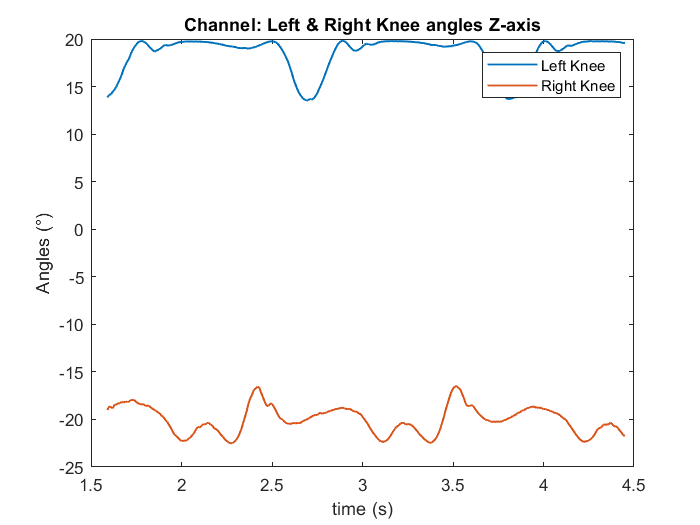

figure('Name','Channel: Left & Right Knee angles Z-axis') %create figure
plot(time_domain,(angles.LKneeangles(:,1)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RKneeangles(:,1)),'LineWidth',1) % plot second data
legend('Left Knee','Right Knee')
hold off % stop hold of plot

## Left and Right Ankle Angle plots

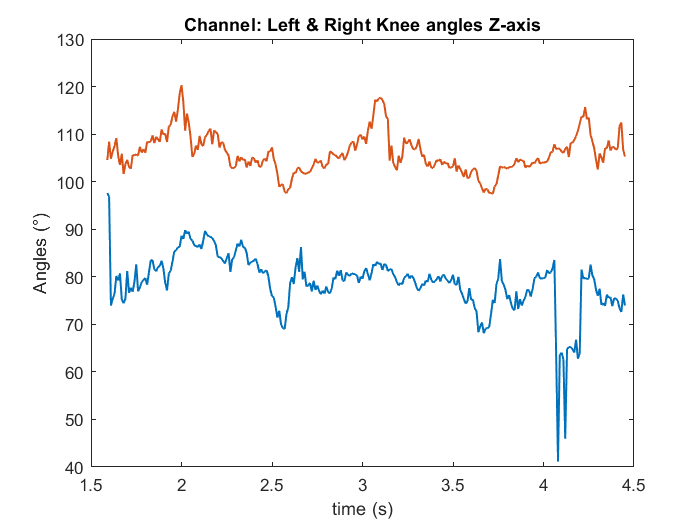

figure('Name','Channel: Left & Right Ankle angles Z-axis') % create figure
plot(time_domain,(angles.LAnkleangles(:,1)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RAnkleangles(:,1)),'LineWidth',1) % plot second data
hold off % stop hold of plot

# Plotting Y - axis angles 

## Left and Right Hip Angle plot

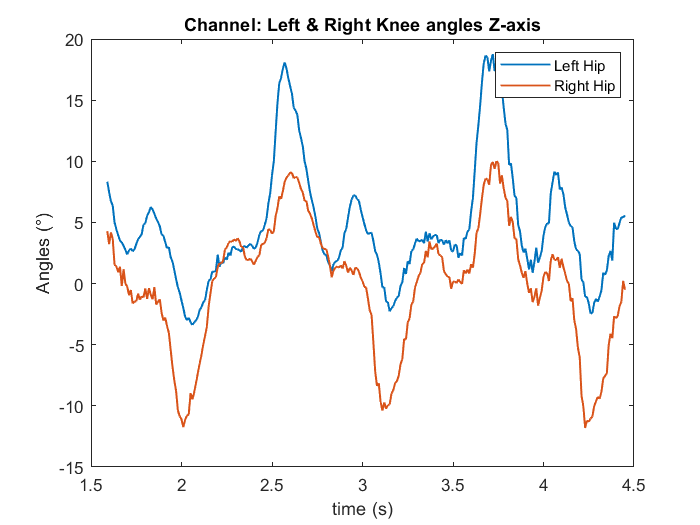

figure('Name','Channel: Left & Right Hip angles Z-axis') %create figure
plot(time_domain,(angles.LHipangles(:,2)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RHipangles(:,2)),'LineWidth',1) % plot second data
legend('Left Hip','Right Hip') % label data points
hold off % stop hold of plot

## Left and Right Knee Angle plot

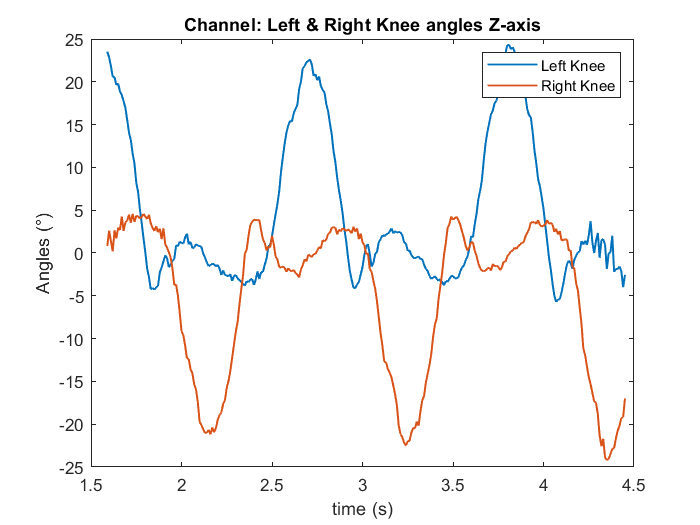

figure('Name','Channel: Left & Right Knee angles Z-axis') %create figure
plot(time_domain,(angles.LKneeangles(:,2)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RKneeangles(:,2)),'LineWidth',1) % plot second data
legend('Left Knee','Right Knee')
hold off % stop hold of plot

## Left and Right Ankle Angle plots

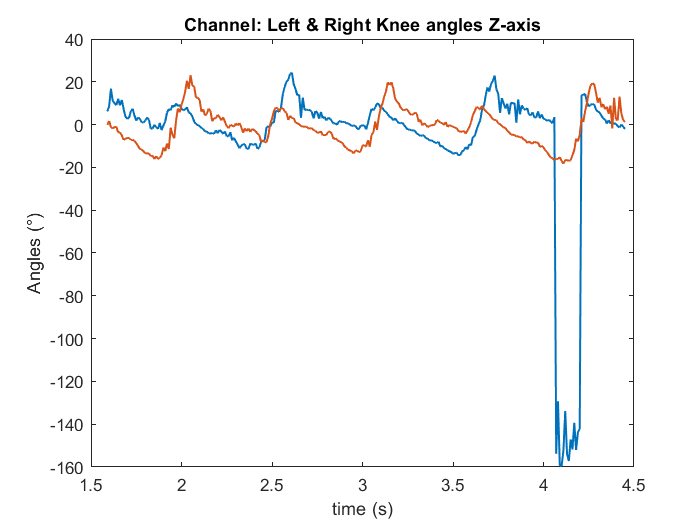

figure('Name','Channel: Left & Right Ankle angles Z-axis') % create figure
plot(time_domain,(angles.LAnkleangles(:,2)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RAnkleangles(:,2)),'LineWidth',1) % plot second data
hold off % stop hold of plot

# Plotting  Z - axis angles 

## Left and Right Hip Angle plot

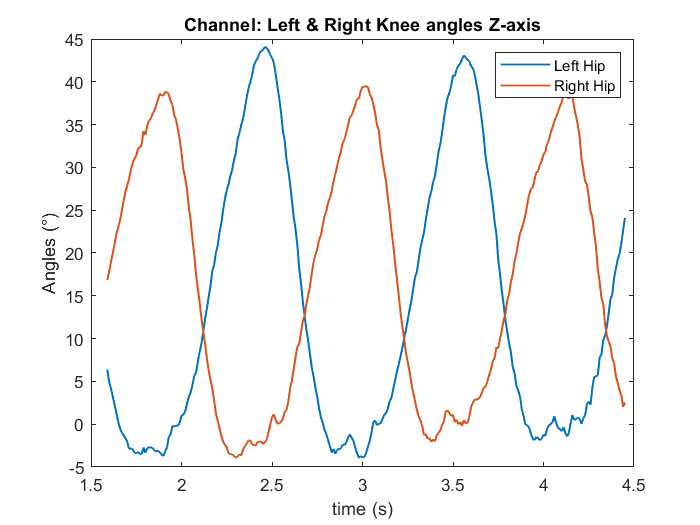

figure('Name','Channel: Left & Right Hip angles Z-axis') %create figure
plot(time_domain,(angles.LHipangles(:,3)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RHipangles(:,3)),'LineWidth',1) % plot second data
legend('Left Hip','Right Hip') % label data points
hold off % stop hold of plot

## Left and Right Knee Angle plot

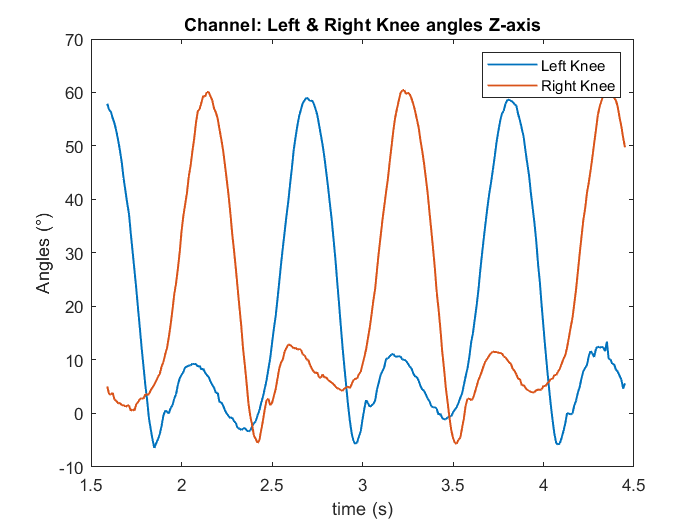

figure('Name','Channel: Left & Right Knee angles Z-axis') %create figure
plot(time_domain,(angles.LKneeangles(:,3)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RKneeangles(:,3)),'LineWidth',1) % plot second data
legend('Left Knee','Right Knee')
hold off % stop hold of plot

## Left and Right Ankle Angle plots

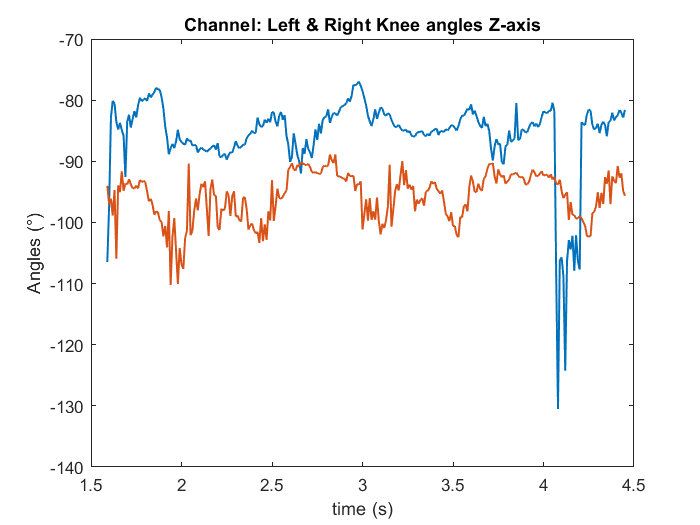

figure('Name','Channel: Left & Right Ankle angles Z-axis') % create figure
plot(time_domain,(angles.LAnkleangles(:,3)),'LineWidth',1) % plot first data
title ('Channel: Left & Right Knee angles Z-axis')  % title plot
xlabel('time (s)')  % label x axis
ylabel('Angles (°)') % label y axis
hold on % hold the plot
plot(time_domain,(angles.RAnkleangles(:,3)),'LineWidth',1) % plot second data
hold off % stop hold of plot